# Data analysis for the LM_model

This is the data analysis of the Laguna Multispecies bioeconomic model for the casting net, gillnet and shrimp fyke net gears harvesting the bottlenose-dolphin, the lebranch mullet and the pink shrimp.

## Loading variables

load LM_variables.mat lm_gear lm_sp T

## Creating matrices and vectors for the LM package

Initial Fishing effort column vector (E0)

E0 = lm_gear.f; % days of fishing

Catchability matrix (Q)

Q = [lm_gear.q_bd lm_gear.q_lm lm_gear.q_ps]; % percentage of the stock

Initial stock size row vector (X0)

X0 = lm_sp.x0'; % Biomass in tons

Elasticity coefficients for the Coob-Douglas harvest function matrices (Al, Be)

Al = [lm_gear.al_bd lm_gear.al_lm lm_gear.al_ps]; % dimensionless
Be = [lm_gear.be_bd lm_gear.be_lm lm_gear.be_ps]; % dimensionless

Market price matrix (P)

P = [lm_gear.p_bd lm_gear.p_lm lm_gear.p_ps]; % reais per tonnes

Cost per unit of fishing effort column vector (C)

C = lm_gear.c; % reais

Other and labor costs percentage column vectors (O, L) 

O = lm_gear.o; % Percentage
L = lm_gear.l; % Percentage

Oportunity rate column vector (O_rate)

O_rate = lm_gear.oRate; %Percentage

Growth matrix

G={lm_sp.growth_type, lm_sp.growth_par}; % Type of growth and growth parameters

Interaction matrix

I = [lm_sp.ibd'; lm_sp.ilm'; lm_sp.ips']; % Interaction coefficients

Number of species

N = size(X0,2);

Number of gears

M = size(E0,1);

## Base Scenario

NS = 1000; % number of simulations

% pre allocate for simulations
XS_BS = zeros(T+1,N,NS);
ES_BS = zeros(M,T+1,NS);
PCLIS_BS = zeros(M, T, NS);
LES_BS = zeros(M+1, T, NS);
BS_t_S = cell(1,NS); 

% simulations loop
for i=1:NS
NPV = LM_NPV_NC_Evar(E0, lm_gear.di, Q, X0, Al, Be, P, C, O, L, O_rate, T, G, I);
% NPV for 25 years of fishing
load LM_NPV_Evar_var.mat x E NC_t PCLI LE %import variables

XS_BS(:,:,i) = x;
ES_BS(:,:,i) = E;
PCLIS_BS(:,:,i) = PCLI;
LES_BS(:,:,i) = LE;
BS_t_S{i} = NC_t;
end
%mean 
x_BS = mean(XS_BS,3);
E_BS = mean(ES_BS,3);
PCLI_BS = mean(PCLIS_BS,3);
LE_BS = mean(LES_BS,3);

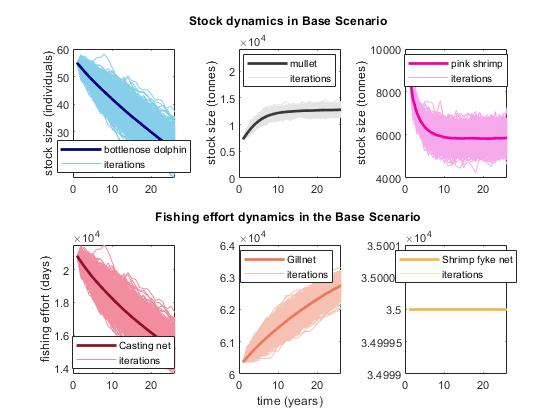

tl_BS = tiledlayout(2,3);

nexttile(1,[1 1])
%Ploting bd stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#87ceeb'); 
hold on
for i=1:NS
plot(XS_BS(:, 1, i), 'color','#87ceeb');
end
p3 = plot(x_BS(:, 1), 'color', '#000080',"LineWidth",2);
hold off
legend([p3 p1],'bottlenose dolphin', 'iterations','Location',"best")
ylabel('stock size (individuals)')
%xlabel('time (years)')
%title ('Stock dynamics in the multiespecies bioeconomic model')
%ylim([0 K_bd])

nexttile(2,[1 1])
%Ploting lm stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#e5e4e2'); 
hold on
for i=1:NS
plot(XS_BS(:, 2, i), 'color','#e5e4e2');
end
p3 = plot(x_BS(:, 2), 'color', '#353839',"LineWidth",2);
hold off
legend([p3 p1],'mullet', 'iterations','Location',"best")
ylabel('stock size (tonnes)')
%xlabel('time (years)')
title (['Stock dynamics in Base Scenario', ' '])
subtitle('   ')
ylim([0 K_lm])

nexttile(3,[1 1])
%Ploting ps stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f5a8ea'); 
hold on
for i=1:NS
plot(XS_BS(:, 3, i), 'color','#f5a8ea');
end
p3 = plot(x_BS(:, 3), 'color', '#f400a1',"LineWidth",2);
hold off
legend([p3 p1],'pink shrimp', 'iterations','Location',"best")
ylabel('stock size (tonnes)')
%xlabel('time (years)')
%title ('Stock dynamics in the multiespecies bioeconomic model')
%ylim([0 K_bd])

nexttile(4,[1 1])
%Ploting Cast fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(ES_BS(1, :, i), 'color','#f18d9f');
end
p3 = plot(E_BS(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('fishing effort (days)')
%xlabel('time (years)')
%title (['Stock dynamics in the multiespecies bioeconomic model', ' '])
%ylim([0 K_bd])

nexttile(5,[1 1])
%Ploting Gill fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(ES_BS(2, :, i), 'color','#f6c1b2');
end
p3 = plot(E_BS(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Fishing effort dynamics in the Base Scenario', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(6,[1 1])
%Ploting Fyke fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(ES_BS(3, :, i), 'color','#f6e3b6');
end
p3 = plot(E_BS(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
%xlabel('time (years)')
%title (['Fishing effort in the Base Scenario', ' '])
%ylim([0 K_bd])
tiledlayout(1,1)

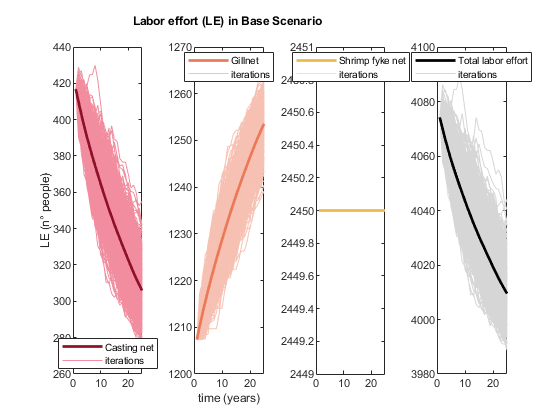

%ploting LE for each gear
tl_BS = tiledlayout(1,4);

nexttile(1,[1 1])
%Ploting Casting net LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(LES_BS(1, :, i), 'color','#f18d9f');
end
p3 = plot(LE_BS(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('LE (n° people)')

nexttile(2,[1 1])
%Ploting gillnet LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(LES_BS(2, :, i), 'color','#f6c1b2');
end
p3 = plot(LE_BS(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Labor effort (LE) in Base Scenario', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(3,[1 1])
%Ploting Fyke LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(LES_BS(3, :, i), 'color','#f6e3b6');
end
p3 = plot(LE_BS(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")

nexttile(4,[1 1])
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#d6d6d6'); 
hold on
for i=1:NS
plot(LES_BS(4, :, i), 'color','#d6d6d6');
end
p3 = plot(LE_BS(4, :), 'color', '#000000',"LineWidth",2);
hold off
legend([p3 p1],'Total labor effort', 'iterations','Location',"best")
tiledlayout(1,1)

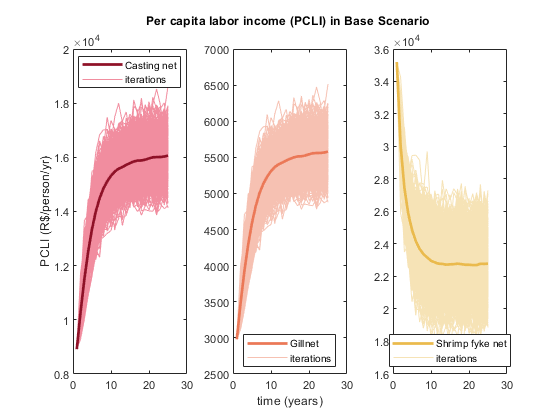

%ploting PCLI for each gear
tl_BS = tiledlayout(1,3);

nexttile(1,[1 1])
%Ploting Casting net PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(PCLIS_BS(1, :, i), 'color','#f18d9f');
end
p3 = plot(PCLI_BS(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('PCLI (R$/person/yr)')

nexttile(2,[1 1])
%Ploting gillnet PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(PCLIS_BS(2, :, i), 'color','#f6c1b2');
end
p3 = plot(PCLI_BS(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Per capita labor income (PCLI) in Base Scenario', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(3,[1 1])
%Ploting Fyke PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(PCLIS_BS(3, :, i), 'color','#f6e3b6');
end
p3 = plot(PCLI_BS(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")

tiledlayout(1,1)

BS_t = NC_t;
for i = 1:NS-1
    BS_t.mean_fishing_effort = BS_t.mean_fishing_effort + BS_t_S{i}.mean_fishing_effort;
    BS_t.mean_harvest_1 = BS_t.mean_harvest_1 + BS_t_S{i}.mean_harvest_1;
    BS_t.mean_harvest_2 = BS_t.mean_harvest_2 + BS_t_S{i}.mean_harvest_2;
    BS_t.mean_harvest_3 = BS_t.mean_harvest_3 + BS_t_S{i}.mean_harvest_3;
    BS_t.NPV = BS_t.NPV + BS_t_S{i}.NPV;
    BS_t.LE = BS_t.LE + BS_t_S{i}.LE;
    BS_t.TLI = BS_t.TLI + BS_t_S{i}.TLI;
    BS_t.PCLI = BS_t.PCLI + BS_t_S{i}.PCLI;
end

BS_t.mean_fishing_effort = BS_t.mean_fishing_effort./NS;
BS_t.mean_harvest_1 = BS_t.mean_harvest_1./NS;
BS_t.mean_harvest_2 = BS_t.mean_harvest_2./NS;
BS_t.mean_harvest_3 = BS_t.mean_harvest_3./NS;
BS_t.NPV = BS_t.NPV./NS;
BS_t.LE = BS_t.LE./NS;
BS_t.TLI = BS_t.TLI./NS;
BS_t.PCLI = BS_t.PCLI./NS;

BS_t = [lm_gear.Gear BS_t] % Show table

BS_t = 3×9 table
         Var1          mean_fishing_effort    mean_harvest_1    mean_harvest_2    mean_harvest_3       NPV          LE         TLI         PCLI 
    _______________    ___________________    ______________    ______________    ______________    __________    ______    __________    ______

    {'Casting net'}           18329                    0            410.81            0.11044       7.5618e+07    366.59    7.5618e+07      8252
    {'Gillnet'    }           64167               1.5606            2168.3           0.038084       8.8849e+07    1283.3     1.702e+08    5304.7
    {'Fyke net'   }           36400                    0            1.2527             2596.7   

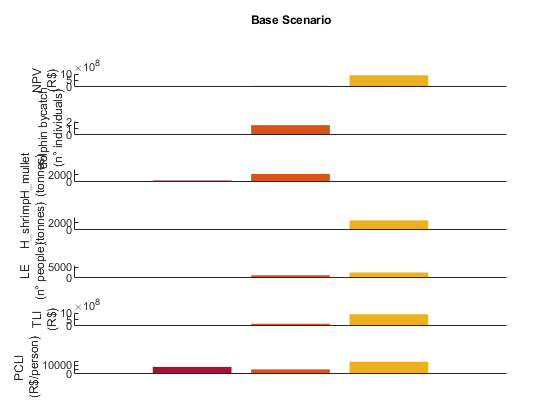


%ploting table information in bar plots
tl = tiledlayout(14,1);

nexttile(1,[2 1])
b_E = bar(BS_t.NPV);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
title({"Base Scenario",'','',''})
ylabel({'NPV', '(R$)'})
ylim([0 10E8])

nexttile(3,[2 1])
b_E = bar(BS_t.mean_harvest_1);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'dolphin bycatch', '(n° individuals)'})
ylim([0 2.2])

nexttile(5,[2 1])
b_E = bar(BS_t.mean_harvest_2);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'H\_mullet', '(tonnes)'})
ylim([0 3500])

nexttile(7,[2 1])
b_E = bar(BS_t.mean_harvest_3);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'H\_shrimp', '(tonnes)'})
ylim([0 3500])

nexttile(9,[2 1])
b_E = bar(BS_t.LE);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'LE', '(n° people)'})
ylim([0 6000])

nexttile(11,[2 1])
b_E = bar(BS_t.TLI);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'TLI', '(R$)'})
ylim([0 10E8])

nexttile(13,[2 1])
b_E = bar(BS_t.PCLI);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'PCLI', '(R$/person)'})
ylim([0 15000])

tiledlayout(1,1);

## Open Acess

% pre allocate for simulations
E_incr = 0.05;
XS_OA = zeros(T+1,N,NS);
ES_OA = zeros(M,T+1,NS);
PCLIS_OA = zeros(M,T,NS);
LES_OA = zeros(M+1,T,NS);
OA_t_S = cell(1,NS); 

%loop for simulations
for i=1:NS
NPV = LM_NPV_OA_Evar(E0, lm_gear.di, Q, X0, Al, Be, P, C, O, L, O_rate, T, G, I, E_incr);
load LM_NPV_OA_Evar_var.mat E x PCLI LE OA_t %Computing NPV and stock for the current year
    
XS_OA(:,:,i) = x;
ES_OA(:,:,i) = E;
PCLIS_OA(:,:,i) = PCLI;
LES_OA(:,:,i)=LE;
OA_t_S{i} = OA_t;

end
%end of simulations
%mean 
x_OA = mean(XS_OA,3);
E_OA = mean(ES_OA,3);
LE_OA=mean(LES_OA,3);
PCLI_OA=mean(PCLIS_OA,3);

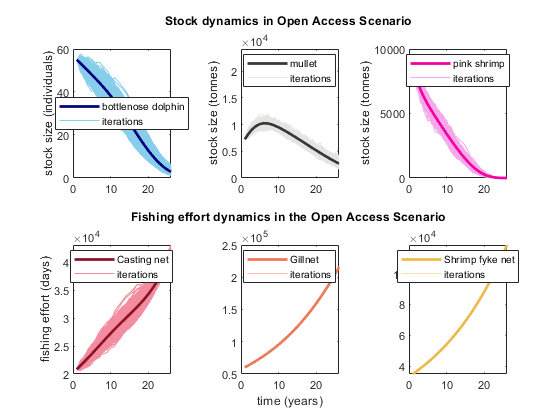

tl_OA = tiledlayout(2,3);

nexttile(1,[1 1])
%Ploting bd stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#87ceeb'); 
hold on
for i=1:NS
plot(XS_OA(:, 1, i), 'color','#87ceeb');
end
p3 = plot(x_OA(:, 1), 'color', '#000080',"LineWidth",2);
hold off
legend([p3 p1],'bottlenose dolphin', 'iterations','Location',"best")
ylabel('stock size (individuals)')
%xlabel('time (years)')
%title ('Stock dynamics in the multiespecies bioeconomic model')
%ylim([0 K_bd])

nexttile(2,[1 1])
%Ploting lm stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#e5e4e2'); 
hold on
for i=1:NS
plot(XS_OA(:, 2, i), 'color','#e5e4e2');
end
p3 = plot(x_OA(:, 2), 'color', '#353839',"LineWidth",2);
hold off
legend([p3 p1],'mullet', 'iterations','Location',"best")
ylabel('stock size (tonnes)')
%xlabel('time (years)')
title (['Stock dynamics in Open Access Scenario', ' '])
subtitle('   ')
ylim([0 K_lm])

nexttile(3,[1 1])
%Ploting ps stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f5a8ea'); 
hold on
for i=1:NS
plot(XS_OA(:, 3, i), 'color','#f5a8ea');
end
p3 = plot(x_OA(:, 3), 'color', '#f400a1',"LineWidth",2);
hold off
legend([p3 p1],'pink shrimp', 'iterations','Location',"best")
ylabel('stock size (tonnes)')
%xlabel('time (years)')
%title ('Stock dynamics in the multiespecies bioeconomic model')
%ylim([0 K_bd])

nexttile(4,[1 1])
%Ploting Cast fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(ES_OA(1, :, i), 'color','#f18d9f');
end
p3 = plot(E_OA(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('fishing effort (days)')
%xlabel('time (years)')
%title (['Stock dynamics in the multiespecies bioeconomic model', ' '])
%ylim([0 K_bd])

nexttile(5,[1 1])
%Ploting Gill fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(ES_OA(2, :, i), 'color','#f6c1b2');
end
p3 = plot(E_OA(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Fishing effort dynamics in the Open Access Scenario', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(6,[1 1])
%Ploting Fyke fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(ES_OA(3, :, i), 'color','#f6e3b6');
end
p3 = plot(E_OA(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
%xlabel('time (years)')
%title (['Fishing effort in the Base Scenario', ' '])
%ylim([0 K_bd])

tiledlayout(1,1)

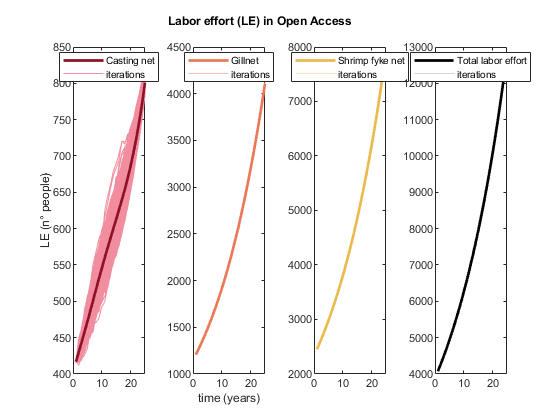

%ploting LE for each gear
tl_OA = tiledlayout(1,4);

nexttile(1,[1 1])
%Ploting Casting net LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(LES_OA(1, :, i), 'color','#f18d9f');
end
p3 = plot(LE_OA(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('LE (n° people)')

nexttile(2,[1 1])
%Ploting gillnet LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(LES_OA(2, :, i), 'color','#f6c1b2');
end
p3 = plot(LE_OA(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['                    Labor effort (LE) in Open Access', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(3,[1 1])
%Ploting Fyke LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(LES_OA(3, :, i), 'color','#f6e3b6');
end
p3 = plot(LE_OA(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")

nexttile(4,[1 1])
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#d6d6d6'); 
hold on
for i=1:NS
plot(LES_OA(4, :, i), 'color','#d6d6d6');
end
p3 = plot(LE_OA(4, :), 'color', '#000000',"LineWidth",2);
hold off
legend([p3 p1],'Total labor effort', 'iterations','Location',"best")
tiledlayout(1,1)

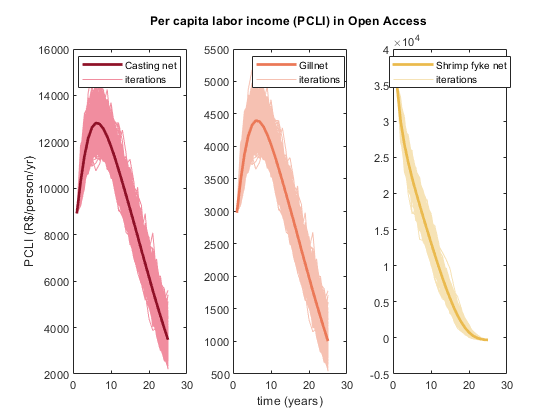

%ploting PCLI for each gear
tl_OA = tiledlayout(1,3);

nexttile(1,[1 1])
%Ploting Cast PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(PCLIS_OA(1, :, i), 'color','#f18d9f');
end
p3 = plot(PCLI_OA(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('PCLI (R$/person/yr)')

nexttile(2,[1 1])
%Ploting gillnet PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(PCLIS_OA(2, :, i), 'color','#f6c1b2');
end
p3 = plot(PCLI_OA(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Per capita labor income (PCLI) in Open Access', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(3,[1 1])
%Ploting Fyke PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(PCLIS_OA(3, :, i), 'color','#f6e3b6');
end
p3 = plot(PCLI_OA(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")

tiledlayout(1,1)

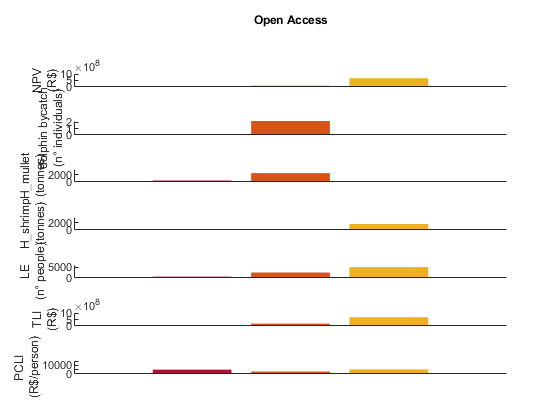


for i = 1:NS-1
    OA_t.mean_fishing_effort = OA_t.mean_fishing_effort + OA_t_S{i}.mean_fishing_effort;
    OA_t.mean_harvest_1 = OA_t.mean_harvest_1 + OA_t_S{i}.mean_harvest_1;
    OA_t.mean_harvest_2 = OA_t.mean_harvest_2 + OA_t_S{i}.mean_harvest_2;
    OA_t.mean_harvest_3 = OA_t.mean_harvest_3 + OA_t_S{i}.mean_harvest_3;
    OA_t.NPV = OA_t.NPV + OA_t_S{i}.NPV;
    OA_t.LE = OA_t.LE + OA_t_S{i}.LE;
    OA_t.TLI = OA_t.TLI + OA_t_S{i}.TLI;
    OA_t.PCLI = OA_t.PCLI + OA_t_S{i}.PCLI;
end

OA_t.mean_fishing_effort = OA_t.mean_fishing_effort./NS;
OA_t.mean_harvest_1 = OA_t.mean_harvest_1./NS;
OA_t.mean_harvest_2 = OA_t.mean_harvest_2./NS;
OA_t.mean_harvest_3 = OA_t.mean_harvest_3./NS;
OA_t.NPV = OA_t.NPV./NS;
OA_t.LE = OA_t.LE./NS;
OA_t.TLI = OA_t.TLI./NS;
OA_t.PCLI = OA_t.PCLI./NS;

%ploting table information in bar plots
tl_OA = tiledlayout(14,1);

nexttile(1,[2 1])
b_E = bar(OA_t.NPV);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
title({"Open Access",'','',''})
ylabel({'NPV', '(R$)'})
ylim([0 10E8])

nexttile(3,[2 1])
b_E = bar(OA_t.mean_harvest_1);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'dolphin bycatch', '(n° individuals)'})
ylim([0 2.2])

nexttile(5,[2 1])
b_E = bar(OA_t.mean_harvest_2);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'H\_mullet', '(tonnes)'})
ylim([0 3500])


nexttile(7,[2 1])
b_E = bar(OA_t.mean_harvest_3);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'H\_shrimp', '(tonnes)'})
ylim([0 3500])

nexttile(9,[2 1])
b_E = bar(OA_t.LE);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'LE', '(n° people)'})
ylim([0 6000])

nexttile(11,[2 1])
b_E = bar(OA_t.TLI);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'TLI', '(R$)'})
ylim([0 10E8])

nexttile(13,[2 1])
b_E = bar(OA_t.PCLI);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'PCLI', '(R$/person)'})
ylim([0 15000])

tiledlayout(1,1);

## Optimal Management (NPV)

% pre allocate for simulations
E_incr = 0.05;
XS_OM = zeros(T+1,N,NS);
ES_OM = zeros(M,T+1,NS);
PCLIS_OM = zeros(M,T,NS);
LES_OM =zeros(M+1,T,NS);
OM_t_S = cell(1,NS); 

G_OM = {lm_sp.growth_type, {[r_bd, 0, K_bd, 0];
    [r_lm, 0, K_lm, 0, m_lm, 0];
    [r_ps, 0, K_ps, 0]; }};

fNPV=@(y) -sum(LM_NPV_NC_Evar([y(1) y(2) y(3)]',lm_gear.di, Q, X0, Al, Be, P, C, O, L, O_rate, T, G_OM, I)); %Creates the function for otimization
format long
E_OM_sol = fmincon(fNPV,E0*0.3,[],[],[],[],[0 0 0],[E0(1)*2 E0(2)*2 E0(3)*2])


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


E_OM_sol = 	1.0e+04 *

   4.168199999995870
   0.000000000039382
   3.215862180921476


format short

E_OM_sol(2,1)=0;

%loop for simulations
for i=1:NS

LM_NPV_NC_Evar(E_OM_sol,lm_gear.di, Q, X0, Al, Be, P, C, O, L, O_rate, T, G, I); 
load LM_NPV_Evar_var.mat E x PCLI LE NC_t % Compute results for the optimal fishing effort

XS_OM(:,:,i) = x;
ES_OM(:,:,i) = E;
PCLIS_OM(:,:,i) = PCLI;
LES_OM(:,:,i) = LE;
OM_t_S{i} = NC_t;
end
%end of simulations

%mean 
x_OM = mean(XS_OM,3);
E_OM = mean(ES_OM,3);
LE_OM = mean(LES_OM,3);
PCLI_OM = mean(PCLIS_OM,3);

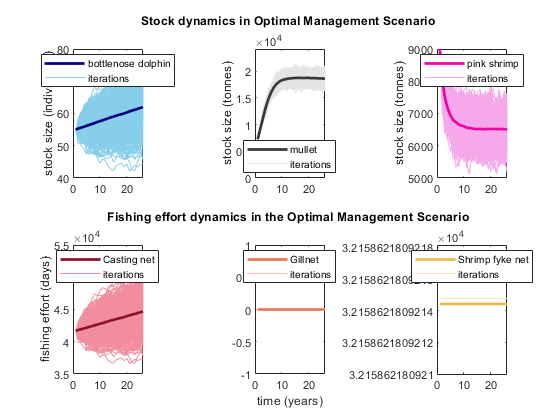

tl_OM = tiledlayout(2,3);

nexttile(1,[1 1])
%Ploting bd stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#87ceeb'); 
hold on
for i=1:NS
plot(XS_OM(:, 1, i), 'color','#87ceeb');
end
p3 = plot(x_OM(:, 1), 'color', '#000080',"LineWidth",2);
hold off
legend([p3 p1],'bottlenose dolphin', 'iterations','Location',"best")
ylabel('stock size (individuals)')
%xlabel('time (years)')
%title ('Stock dynamics in the multiespecies bioeconomic model')
%ylim([0 K_bd])

nexttile(2,[1 1])
%Ploting lm stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#e5e4e2'); 
hold on
for i=1:NS
plot(XS_OM(:, 2, i), 'color','#e5e4e2');
end
p3 = plot(x_OM(:, 2), 'color', '#353839',"LineWidth",2);
hold off
legend([p3 p1],'mullet', 'iterations','Location',"best")
ylabel('stock size (tonnes)')
%xlabel('time (years)')
title (['Stock dynamics in Optimal Management Scenario', ' '])
subtitle('   ')
ylim([0 K_lm])

nexttile(3,[1 1])
%Ploting ps stock dynamics 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f5a8ea'); 
hold on
for i=1:NS
plot(XS_OM(:, 3, i), 'color','#f5a8ea');
end
p3 = plot(x_OM(:, 3), 'color', '#f400a1',"LineWidth",2);
hold off
legend([p3 p1],'pink shrimp', 'iterations','Location',"best")
ylabel('stock size (tonnes)')
%xlabel('time (years)')
%title ('Stock dynamics in the multiespecies bioeconomic model')
%ylim([0 K_bd])

nexttile(4,[1 1])
%Ploting Cast fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(ES_OM(1, :, i), 'color','#f18d9f');
end
p3 = plot(E_OM(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('fishing effort (days)')
%xlabel('time (years)')
%title (['Stock dynamics in the multiespecies bioeconomic model', ' '])
%ylim([0 40000])

nexttile(5,[1 1])
%Ploting Gill fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(ES_OM(2, :, i), 'color','#f6c1b2');
end
p3 = plot(E_OM(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Fishing effort dynamics in the Optimal Management Scenario', ' '])
subtitle('   ')
%ylim([0 40000])

nexttile(6,[1 1])
%Ploting Fyke fishing effort 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(ES_OM(3, :, i), 'color','#f6e3b6');
end
p3 = plot(E_OM(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
%xlabel('time (years)')
%title (['Fishing effort in the Base Scenario', ' '])
%ylim([0 30000])

tiledlayout(1,1)

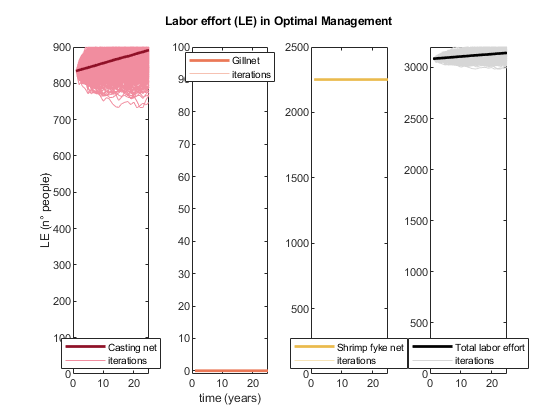

%ploting LE for each gear
tl_OM = tiledlayout(1,4);

nexttile(1,[1 1])
%Ploting Casting net LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(LES_OM(1, :, i), 'color','#f18d9f');
end
p3 = plot(LE_OM(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('LE (n° people)')
ylim([0 900])

nexttile(2,[1 1])
%Ploting gillnet LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(LES_OM(2, :, i), 'color','#f6c1b2');
end
p3 = plot(LE_OM(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['                               Labor effort (LE) in Optimal Management', ' '])
subtitle('   ')
ylim([-1 100])

nexttile(3,[1 1])
%Ploting Fyke LE 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(LES_OM(3, :, i), 'color','#f6e3b6');
end
p3 = plot(LE_OM(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")
ylim([0 2500])

nexttile(4,[1 1])
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#d6d6d6'); 
hold on
for i=1:NS
plot(LES_OM(4, :, i), 'color','#d6d6d6');
end
p3 = plot(LE_OM(4, :), 'color', '#000000',"LineWidth",2);
hold off
legend([p3 p1],'Total labor effort', 'iterations','Location',"best")
ylim([0 3200])

tiledlayout(1,1)

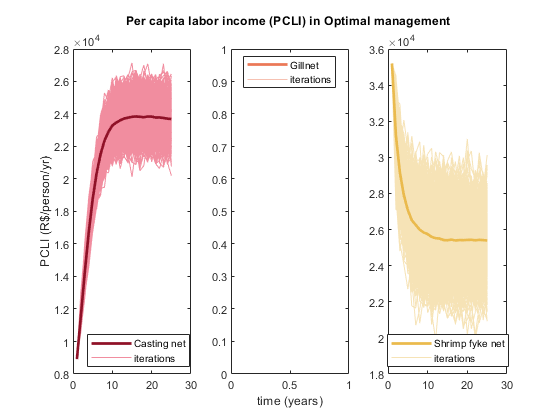

%ploting PCLI for each gear
tl_OM= tiledlayout(1,3);

nexttile(1,[1 1])
%Ploting Casting net PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f18d9f'); 
hold on
for i=1:NS
plot(PCLIS_OM(1, :, i), 'color','#f18d9f');
end
p3 = plot(PCLI_OM(1, :), 'color', '#8f1127',"LineWidth",2);
hold off
legend([p3 p1],'Casting net', 'iterations','Location',"best")
ylabel('PCLI (R$/person/yr)')

nexttile(2,[1 1])
%Ploting gillnet PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6c1b2'); 
hold on
for i=1:NS
plot(PCLIS_OM(2, :, i), 'color','#f6c1b2');
end
p3 = plot(PCLI_OM(2, :), 'color', '#eb7857',"LineWidth",2);
hold off
legend([p3 p1],'Gillnet', 'iterations','Location',"best")
%ylabel('fishing effort (days)')
xlabel('time (years)')
title (['Per capita labor income (PCLI) in Optimal management', ' '])
subtitle('   ')
%ylim([0 K_bd])

nexttile(3,[1 1])
%Ploting Fyke PCLI 
p1 = plot([NaN NaN],[NaN NaN],'-',"color",'#f6e3b6'); 
hold on
for i=1:NS
plot(PCLIS_OM(3, :, i), 'color','#f6e3b6');
end
p3 = plot(PCLI_OM(3, :), 'color', '#eaba4d',"LineWidth",2);
hold off
legend([p3 p1],'Shrimp fyke net', 'iterations','Location',"best")

tiledlayout(1,1)

for i = 1:NS-1
    NC_t.mean_fishing_effort = NC_t.mean_fishing_effort + OM_t_S{i}.mean_fishing_effort;
    NC_t.mean_harvest_1 = NC_t.mean_harvest_1 +OM_t_S{i}.mean_harvest_1;
    NC_t.mean_harvest_2 = NC_t.mean_harvest_2 + OM_t_S{i}.mean_harvest_2;
    NC_t.mean_harvest_3 = NC_t.mean_harvest_3 + OM_t_S{i}.mean_harvest_3;
    NC_t.NPV = NC_t.NPV + OM_t_S{i}.NPV;
    NC_t.LE = NC_t.LE + OM_t_S{i}.LE;
    NC_t.TLI = NC_t.TLI + OM_t_S{i}.TLI;
    NC_t.PCLI = NC_t.PCLI + OM_t_S{i}.PCLI;
end

NC_t.mean_fishing_effort = NC_t.mean_fishing_effort./NS;
NC_t.mean_harvest_1 = NC_t.mean_harvest_1./NS;
NC_t.mean_harvest_2 = NC_t.mean_harvest_2./NS;
NC_t.mean_harvest_3 = NC_t.mean_harvest_3./NS;
NC_t.NPV = NC_t.NPV./NS;
NC_t.LE = NC_t.LE./NS;
NC_t.TLI = NC_t.TLI./NS;
NC_t.PCLI = NC_t.PCLI./NS;
%Relative fishing effort
E_OM_sol./E0

ans =     2.0000
         0
    0.9188


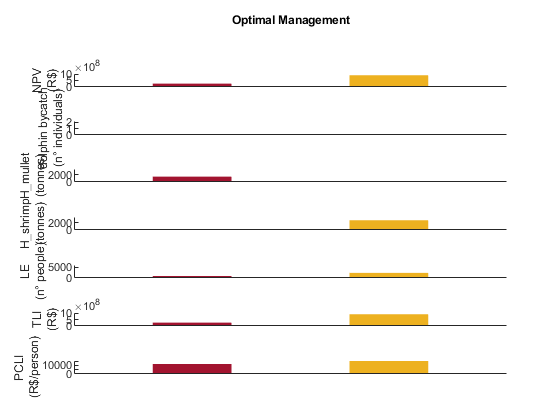

OM_t = NC_t;

%ploting table information in bar plots
tl_OM = tiledlayout(14,1);

nexttile(1,[2 1])
b_E = bar(OM_t.NPV);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
title({"Optimal Management",'','',''})
ylabel({'NPV', '(R$)'})
ylim([0 10E8])

nexttile(3,[2 1])
b_E = bar(OM_t.mean_harvest_1);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'dolphin bycatch', '(n° individuals)'})
ylim([0 2.2])

nexttile(5,[2 1])
b_E = bar(OM_t.mean_harvest_2);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'H\_mullet', '(tonnes)'})
ylim([0 3500])


nexttile(7,[2 1])
b_E = bar(OM_t.mean_harvest_3);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'H\_shrimp', '(tonnes)'})
ylim([0 3500])

nexttile(9,[2 1])
b_E = bar(OM_t.LE);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'LE', '(n° people)'})
ylim([0 6000])

nexttile(11,[2 1])
b_E = bar(OM_t.TLI);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'TLI', '(R$)'})
ylim([0 10E8])

nexttile(13,[2 1])
b_E = bar(OM_t.PCLI);
b_E.EdgeColor="none";
b_E.FaceColor="flat";
b_E.CData(1,:)=[0.6350 0.0780 0.1840];
b_E.CData(2,:)=[0.8500 0.3250 0.0980];
b_E.CData(3,:)=[0.9290 0.6940 0.1250];
set(gca,'xtick', [])
set(gca,'box', 'off')
ylabel({'PCLI', '(R$/person)'})
ylim([0 15000])

tiledlayout(1,1);